# Detailed Frequency Analysis & Peak Detection in MATLAB

## 1. Load Data & Pre-Processing

## Matlab Startup File

This m-File code prepare the enviroment to provide access to auxilliary files and sub-folders.

clear; clc; close all;
format short eng                              
[ProjectFolder,AuxFcn_GS] = AuxFcn_Matlab_Startup_File_001; % Project Startup Folder & Graphical Settings
% Plot Colors
LUCopper = [147, 86, 14]/255;
LUCopper_Light = [225, 213, 199]/255;
LUBlue = [17, 55, 125]/255;
LUBlue_Light = [197, 204, 221]/255;
Red_Dark = [192, 0, 0]/255;
Red_Light = [235, 200, 197]/255;
pink = [255, 199, 206]/255;


load('E2038.mat');   % Suppose data is in a variable pz
% % % % % % % % % % % % % % % % % % % % % % % 
%  Test Mean-subtraction to remove DC offset/baseline
dataTest1 = p(:,1) - mean(p(1:100,1));
dataTest2 = p(:,2) - mean(p(1:100,2));
dataTest3 = p(:,3) - mean(p(1:100,3));
dataTest4 = p(:,4) - mean(p(1:100,4));
dataTest5 = p(:,5) - mean(p(1:100,5));
dataTest6 = p(:,6) - mean(p(1:100,6));
dataTest7 = p(:,7) - mean(p(1:100,7));
dataTest8 = p(:,8) - mean(p(1:100,8));
dataTest9 = p(:,9) - mean(p(1:100,9));
dataTest10 = p(:,10) - mean(p(1:100,10));
dataTest11= p(:,11) - mean(p(1:100,11));
dataTest12 = p(:,12) - mean(p(1:100,12));
% % % % % % % % % % % % % % % % % % % % 
data = dataTest3 * 1000;    % pressure [mbar] Adjust column to your data of interest
test_index = 3;
Fs = fs;             % Sampling frequency in Hz
t = (0:length(data)-1)'/Fs;
% % % % % % % % % % % % % % % % % % % % 
% data_mbar = data*1000;
% data_mbarDiff = [0;diff(data_mbar)];% [mbar]
% PressureRange = 2-(-2); % [bar]
% VoltageRange = 10-(-10); %[V]
% ScalingFactor = PressureRange / VoltageRange;
% data_mVolts = (data / ScalingFactor) * 1000;%[mV]
% dataVoltsDiff = [0;diff(data_mVolts)];
% 
% figure
% subplot(2,1,1)
% plot(t,data_mbar)
% axis tight
% hold on
% subplot(2,1,2)
% plot(t,data_mbarDiff)
% axis tight

% subplot(3,1,2)
% plot(t,data_mVolts)
% axis tight
% hold on
% subplot(3,1,3)
% plot(t,dataVoltsDiff)
% axis tight

% % % % % % % % % % % % % % % % % % % % 
data_Impulse = trapz(t, data);

Table = array2table([mean(data), max(data), min(data),data_Impulse], ...
    'VariableNames', {'Signal Mean [bar]', ...
    'Signal Max [mbar]', ...
    'Signal Min [bar]','Partial Impulse [mbar.s])'});
dataTable = table(Table,'VariableNames',{'Original Signal (DC-Offset-Corrected)'});
disp(dataTable);

                             Original Signal (DC-Offset-Corrected)                         
    _______________________________________________________________________________________

    Signal Mean [bar]    Signal Max [mbar]    Signal Min [bar]    Partial Impulse [mbar.s])
    _________________    _________________    ________________    _________________________
                                                                                           
         8.4557               124.44              -89.436                   5.96           



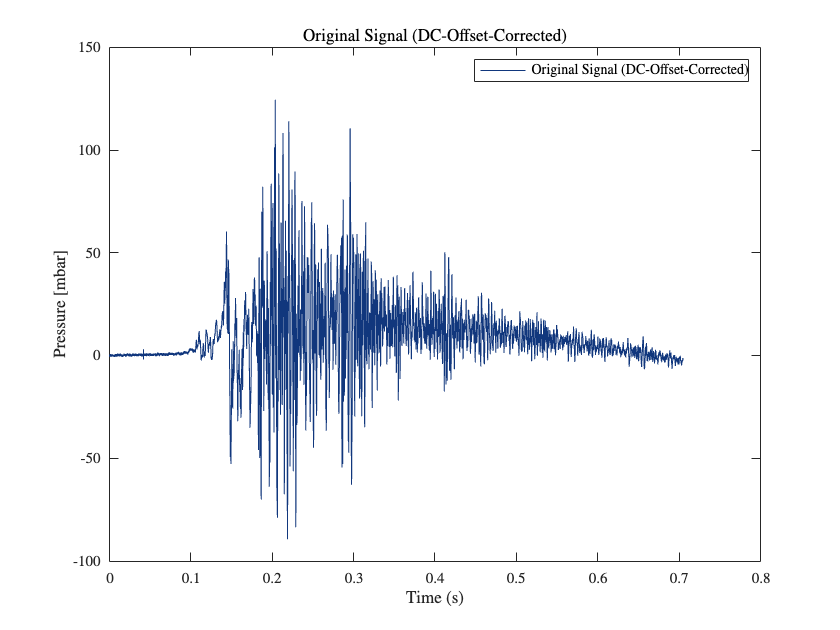


% Quick time-domain plot
figure;
plot(t, data,Color=LUBlue);
xlabel('Time (s)');
ylabel('Pressure [mbar]');
title('Original Signal (DC-Offset-Corrected)');
legend('Original Signal (DC-Offset-Corrected)')

% grid on;

## 2. Detailed Frequency Analysis

### 2.1 Windowing

N = length(data);
window = hanning(N);    % Hanning window
dataWin = data .* window;

### 2.2 Zero-Padding for finer resolution

nfft = 2^nextpow2(N);   % Next power of 2 above N
dataWinPad = [dataWin; zeros(nfft - N,1)];  % zero-padding

### 2.3 Compute FFT & Single-Sided Spectrum

Y = fft(dataWinPad, nfft);
P2 = abs(Y / nfft);     % Two-sided amplitude
P1 = P2(1:nfft/2+1);    % Single-sided amplitude
P1(2:end-1) = 2*P1(2:end-1);

freq = (0:nfft/2)' * Fs / nfft;  % Frequency axis in Hz
% Convert to kHz if desired
% freq_kHz = freq / 1e3;


% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Example MATLAB code to analyze dominant frequencies in a time signal
% % using both FFT and Continuous Wavelet Transform (CWT).
% %
% % Author: [Your Name]
% % Date:   [Date]
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 
% %% 1. Simulate or load your time-domain signal
% %  (Replace this section with your actual time and signal vectors, e.g.:
% %   t = ...;  p = ...; )
% Fs = Fs;             % Sampling frequency (Hz)
% T  = 1/Fs;             % Sampling period
% % Example signal: sum of 200 Hz + 800 Hz + random noise
% p  = p(:,1);
% L  = length(p);
%              % Number of samples
% t  = t;        % Time array (0 to (L-1)*T)
% 
% %% 2. FFT-based spectral analysis
% % Remove any DC offset (optional):
% p_detrend = p - mean(p(1:10));
% % Apply a window if desired (e.g., Hanning):
% window = hann(L);
% p_win  = p_detrend .* window;
% 
% % Compute FFT:
% P  = fft(p_win);
% 
% % Frequency axis (two-sided):
% faxis = (0:L-1)*(Fs/L);
% 
% % Single-sided amplitude spectrum (first half only):
% P_ss   = P(1:floor(L/2));               % first half of spectrum
% Mag_ss = abs(P_ss)/(L/2);               % single-sided magnitude
% faxis_ss = faxis(1:floor(L/2));         % corresponding frequency range
% 
% % Plot the single-sided amplitude spectrum:
% figure('Name','FFT Analysis','NumberTitle','off');
% plot(faxis_ss, Mag_ss, 'b-','LineWidth',1.2);
% xlabel('Frequency (Hz)');
% ylabel('Amplitude');
% title('Single-Sided Amplitude Spectrum');
% grid on;
% 
% %% 3. Continuous Wavelet Transform (Time-Frequency)
% %  The CWT gives frequency content over time (a "scalogram").
% %  Requires the Wavelet Toolbox in MATLAB.
% 
% % Perform the CWT (using default "amor" wavelet here):
% [wt, freq] = cwt(p, 'amor', Fs);  
% %  wt is the complex wavelet coefficients
% %  freq is the associated frequency vector in Hz
% 
% % Convert to magnitude or power:
% cwt_mag = abs(wt);
% 
% % Plot the scalogram:
% figure('Name','Wavelet Scalogram','NumberTitle','off');
% surface(t, freq, cwt_mag);
% axis tight; shading flat;
% set(gca,'YScale','log');    % log-scale freq axis if desired
% xlabel('Time (s)');
% ylabel('Frequency (Hz)');
% title('Continuous Wavelet Transform (Magnitude)');
% colorbar;  % show color scale
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Interpretation:
% % - The FFT plot shows overall spectral content (integrated over entire time).
% % - The CWT plot shows how the signal's frequency components evolve in time.
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


### 2.4 Optional: Power Spectral Density (PSD) approximation

PSD would be (P2.^2) or scaled with 1/(Fs*N), but here we focus on amplitude.

### 2.5 Identify Prominent Peaks

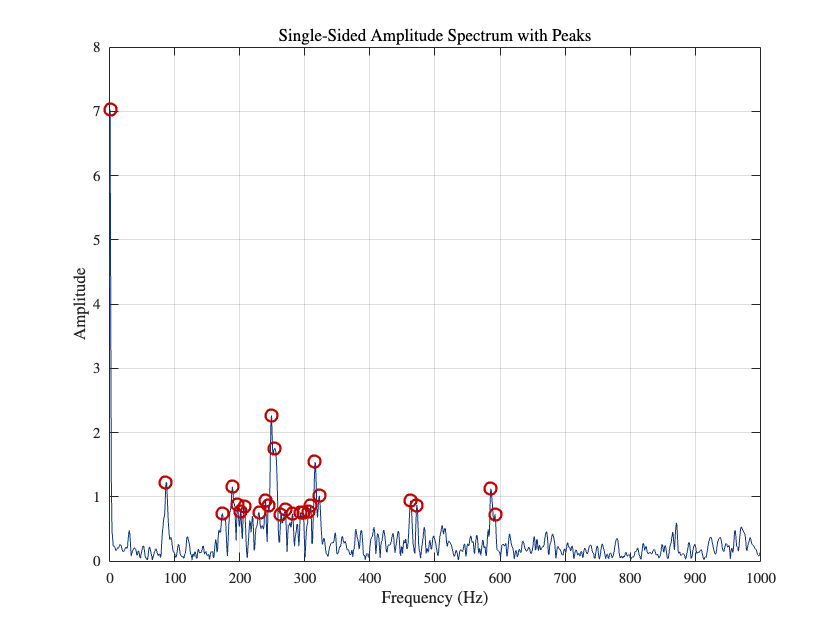

[pks, locs] = findpeaks(P1, 'MinPeakHeight', 0.1*max(P1));
dominantFreqs_Hz = freq(locs);
dominantFreqs_Hz_Max = max(dominantFreqs_Hz);
% Plot the single-sided spectrum with peaks
figure;
plot(freq, P1, 'Color',LUBlue); 
xlim([0 1e3])
hold on;
plot(freq(locs), P1(locs), 'o','MarkerEdgeColor',Red_Dark, 'MarkerSize', 8, 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Single-Sided Amplitude Spectrum with Peaks');

grid on;
hold off;

disp('Dominant Frequencies (Hz):');

Dominant Frequencies (Hz):


disp(dominantFreqs_Hz);

   953.6743e-003
    86.7844e+000
   173.5687e+000
   188.8275e+000
   196.4569e+000
   201.2253e+000
   206.9473e+000
   229.8355e+000
   239.3723e+000
   244.1406e+000
   248.9090e+000
   253.6774e+000
   263.2141e+000
   269.8898e+000
   281.3339e+000
   293.7317e+000
   297.5464e+000
   306.1295e+000
   308.9905e+000
   315.6662e+000
   322.3419e+000
   462.5320e+000
   472.0688e+000
   585.5560e+000
   592.2318e+000



 Use the periodogram function to plot the periodogram of the signal. Then use the pmtm function to plot the smoothed multitaper estimate.

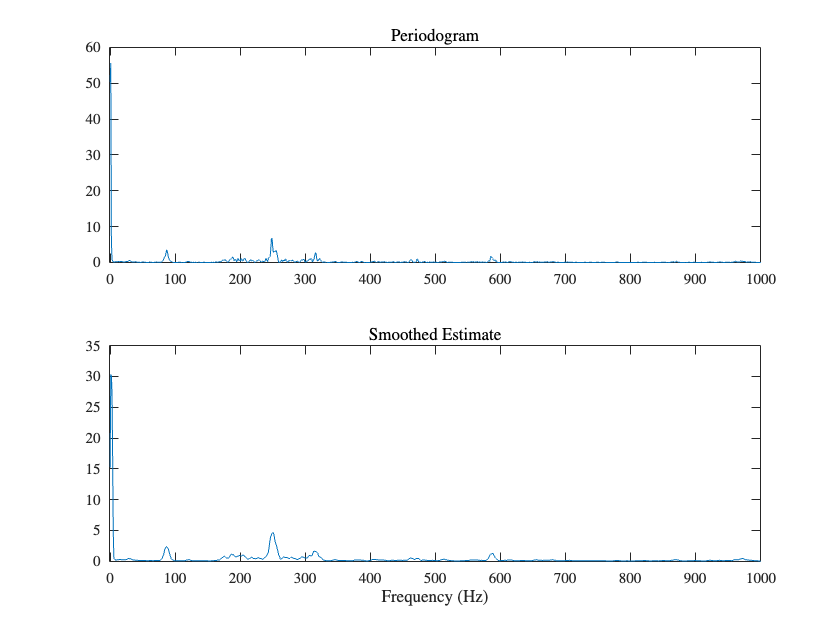

[Pxx,F] = periodogram(data,[],[],Fs);
Pxxmt = pmtm(data,5,[],Fs,'Tapers','sine');

subplot(2,1,1)
plot(F,Pxx)
xlim([-1 1000])
title('Periodogram')
subplot(2,1,2)
plot(F,Pxxmt)
xlim([-1 1000])
title('Smoothed Estimate')
xlabel('Frequency (Hz)')








% N=length(data);
 % x = data;
 % fx=fft(x)/N;
 % f=(0:N-1)*Fs/N;
 % figure
 % plot(f(1:end/2),10*log10(abs(fx(1:end/2))))

 % % % % % % % % 
 % % % % % % % % 
% t = t;
% Cl = data;
% Ts = 1/Fs;
% Fs = Fs;
% Fn = Fs/2;
% L = numel(t);
% Clm = Cl-mean(Cl);                                  % Subtract Mean (Mean = 0 Hz)
% FCl = fft(Clm)/L;
% Fv = linspace(0, 1, fix(L/2)+1)*Fn;
% Iv = 1:numel(Fv);
% 
% [pks,locs] = findpeaks(abs(FCl(Iv))*2, 'MinPeakHeight',0.001);
% 
% figure
% plot(Fv, abs(FCl(Iv))*2)
% grid
% xlim([0 1E3])
% text(Fv(locs), pks, sprintf('\\leftarrow Dominant Frequency = %.2f', Fv(locs)), 'HorizontalAlignment','left')
% % % % % % 
% % % % % % 
% x = data
% x = x - mean(x);                                            % <= ADDED LINE
% plot(t,x), axis('tight'), grid('on'), title('Time series'), figure
% nfft = length(x); % next larger power of 2
% y = fft(x,nfft); % Fast Fourier Transform
% y = abs(y.^2); % raw power spectrum density
% y = y(1:1+nfft/2); % half-spectrum
% [v,k] = max(y); % find maximum
% f_scale = (0:nfft/2)* Fs/nfft; % frequency scale
% plot(f_scale, y),axis('tight'),grid('on'),title('Dominant Frequency')
% fest = f_scale(k); % dominant frequency estimate
% fprintf('Dominant freq.: true %f Hz, estimated %f Hznn\n', fest, fest)
% fprintf('Frequency step (resolution) = %f Hznn\n', f_scale(2))

## 3. Filter Design & Application

Based on the identified peaks, choose a cutoff or band.

## Non-Filtered Data

partialImpulse = trapz(t, data);

Table = array2table([mean(data), max(data), min(data),partialImpulse],'VariableNames', {'Non-Filtered Data Mean [bar]', ...
    'Non-Filtered Data Max [bar]', ...
    'Non-Filtered Data Min [bar]','Non-Filtered Data Impulse [bar.s])'});
lowPassFilterTable = table(Table,'VariableNames',{'Low-Pass Filtered Signal'});
disp(lowPassFilterTable);

                                                        Low-Pass Filtered Signal                                                    
    ________________________________________________________________________________________________________________________________

    Non-Filtered Data Mean [bar]    Non-Filtered Data Max [bar]    Non-Filtered Data Min [bar]    Non-Filtered Data Impulse [bar.s])
    ____________________________    ___________________________    ___________________________    __________________________________
                                                                                                                                    
               8.4557                         124.44                         -89.436                             5.96               



### 3.1 Low-pass filter design (IIR, for example) (lfCut Hz)

 % Example: If the largest peak is well below 45 Hz, you might choose 50 Hz, etc.
% Here we pick some arbitrary cutoff for demonstration. Adjust as needed.
lfCut = dominantFreqs_Hz_Max;
% lfCut = dominantFreqs_Hz_Max + dominantFreqs_Hz_Max*0.2;  % e.g., 50 Hz
lfCut = 1000;

lpFilt = designfilt('lowpassiir', ...
    'FilterOrder', 6, ...
    'HalfPowerFrequency', lfCut, ...
    'SampleRate', Fs);
% Zero-phase filtering
dataLowPass = filtfilt(lpFilt, data);

partialImpulse_Low_Pass = trapz(t, dataLowPass);

Table = array2table([mean(dataLowPass), max(dataLowPass), min(dataLowPass),partialImpulse_Low_Pass],'VariableNames', {'Low-Pass Filter Mean [bar]', ...
    'Low-Pass Filter Max [mbar]', ...
    'Low-Pass Filter Min [mbar]','Partial Impulse [mbar.s])'});
lowPassFilterTable = table(Table,'VariableNames',{'Low-Pass Filtered Signal'});
disp(lowPassFilterTable);

                                                 Low-Pass Filtered Signal                                              
    ___________________________________________________________________________________________________________________

    Low-Pass Filter Mean [bar]    Low-Pass Filter Max [mbar]    Low-Pass Filter Min [mbar]    Partial Impulse [mbar.s])
    __________________________    __________________________    __________________________    _________________________
                                                                                                                       
              8.4556                        103.98                       -81.468                        5.96           



### 3.2 Design high-pass filter (cutoff at Dominant Frequency Hz)

hfCut = dominantFreqs_Hz_Max;
hfCut = 1000;
highpassFilt = designfilt('highpassiir', 'FilterOrder', 4, ...
    'HalfPowerFrequency', hfCut, 'SampleRate', Fs);
dataHighPass = filtfilt(highpassFilt, data);
partialImpulse_High_Pass = trapz(t, dataHighPass);

Table = array2table([mean(dataHighPass), max(dataHighPass), min(dataHighPass), partialImpulse_High_Pass],'VariableNames', {'High-Pass Filter Mean [mbar]', ...
    'High-Pass Filter Max [mbar]', ...
    'High-Pass Filter Min [mbar]','Partial Impulse [mbar.s])'});
highPassFilterTable = table(Table,'VariableNames',{'High-Pass Filtered Signal'});
disp(highPassFilterTable);

                                                   High-Pass Filtered Signal                                               
    _______________________________________________________________________________________________________________________

    High-Pass Filter Mean [mbar]    High-Pass Filter Max [mbar]    High-Pass Filter Min [mbar]    Partial Impulse [mbar.s])
    ____________________________    ___________________________    ___________________________    _________________________
                                                                                                                           
             5.3944e-05                       41.992                         -41.405                     3.8061e-05        



### 3.3 Notch filter for a known fNoise Hz noise (optional)

% fNoise = dominantFreqs_Hz_Max; % Example noise frequency
fNoise = 21; % Example noise frequency
notchFilt = designfilt('bandstopiir','FilterOrder',2, ...
                       'HalfPowerFrequency1', fNoise-2, ...
                       'HalfPowerFrequency2', fNoise+2, ...
                       'SampleRate', Fs);
dataNotch = filtfilt(notchFilt, data);

partialImpulse_Notch = trapz(t, dataNotch);

Table = array2table([mean(dataNotch), max(dataNotch), min(dataNotch), partialImpulse_Notch],'VariableNames', {'Notch Filter Mean [mbar]', ...
    'Notch Filter Max [mbar]', ...
    'Notch Filter Min [mbar]','Partial Impulse [mbar.s])'});
NotchFilterTable = table(Table,'VariableNames',{'Notch Filtered Signal'});
disp(NotchFilterTable);

                                               Notch Filtered Signal                                           
    ___________________________________________________________________________________________________________

    Notch Filter Mean [mbar]    Notch Filter Max [mbar]    Notch Filter Min [mbar]    Partial Impulse [mbar.s])
    ________________________    _______________________    _______________________    _________________________
                                                                                                               
             8.4621                     125.52                     -89.148                     5.9646          



### 3.4 Design band-pass filter (LBF to UBF Hz)

lbfCut = 21;
% ubfCut = dominantFreqs_Hz_Max;
ubfCut = 148;
% bpfilt = designfilt('bandpassfir', ...
%     'FilterOrder', 6, 'CutoffFrequency1', lbfCut, ...
%     'CutoffFrequency2', ubfCut, 'SampleRate', Fs);
% dataBandPass = filtfilt(bpfilt, data);

dataBandPass = bandpass(data,[lbfCut ubfCut],Fs);
partialImpulse_Band_Pass = trapz(t, dataBandPass);

Table = array2table([mean(dataBandPass), max(dataBandPass), min(dataBandPass), partialImpulse_Band_Pass],'VariableNames', {'Band-Pass Filter Mean [mbar]', ...
    'Band-Pass Filter Max [mbar]', ...
    'Band-Pass Filter Min [mbar]','Partial Impulse [mbar.s])'});
BandPassFilterTable = table(Table,'VariableNames',{'Band-Pass Filtered Signal'});
disp(BandPassFilterTable);

                                                   Band-Pass Filtered Signal                                               
    _______________________________________________________________________________________________________________________

    Band-Pass Filter Mean [mbar]    Band-Pass Filter Max [mbar]    Band-Pass Filter Min [mbar]    Partial Impulse [mbar.s])
    ____________________________    ___________________________    ___________________________    _________________________
                                                                                                                           
             0.0049782                        29.651                         -34.078                      0.0035094        



### Plot Time domain

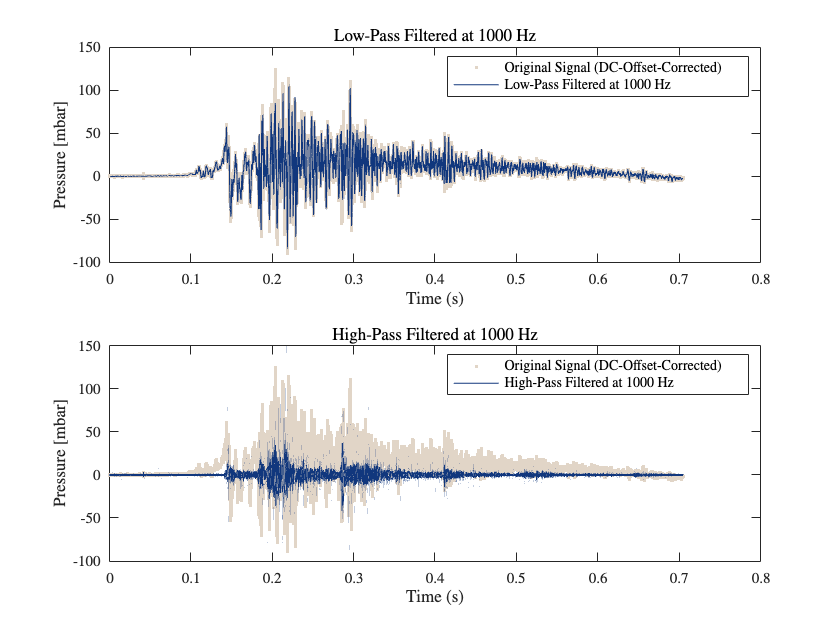

% figure;
%     x0=10;
%     y0=10;
%     width=50;
%     height=10 * 2;
%     set(gcf,'units','centimeters','position',[x0,y0,width,height])
% % % Low-Pass Filtered
% subplot(2,1,1);
% scatter(t, data, '.', ...
%     'MarkerEdgeColor', LUCopper_Light, ...
%     'MarkerEdgeAlpha', 0.2);   % <--- Transparency set here (20% opaque)
% hold on
% plot(t, dataLowPass,'LineWidth', .75, Color=LUBlue); 
% title(sprintf("Low-Pass Filtered at %.0f Hz", lfCut));
% xlabel('Time (s)'); ylabel('Pressure [mbar]');
% legend(sprintf("Low-Pass Filtered at %.0f Hz", lfCut))
% box on
% % Band-Pass Filtered
% subplot(2,1,2);
% scatter(t, data, '.', ...
%     'MarkerEdgeColor', LUCopper_Light, ...
%     'MarkerEdgeAlpha', 0.2);   % <--- Transparency set here (20% opaque)
% hold on
% plot(t, dataBandPass, Color=LUBlue); 
% title(sprintf("Band-Pass Filtered between %.0f and %.0f Hz", lbfCut,ubfCut));
% % grid on;
% xlabel('Time (s)'); ylabel('Pressure [mbar]');
% box on


figure;
subplot(2,1,1);
scatter(t, data, '.', ...
    'MarkerEdgeColor', LUCopper_Light, ...
    'MarkerEdgeAlpha', 1);   % <--- Transparency set here (20% opaque)
hold on
plot(t, dataLowPass,'LineWidth', .75, Color=LUBlue); 
title(sprintf("Low-Pass Filtered at %.0f Hz", lfCut));
% grid on;

xlabel('Time (s)'); ylabel('Pressure [mbar]');
legend('Original Signal (DC-Offset-Corrected)', sprintf("Low-Pass Filtered at %.0f Hz", lfCut))
box on


subplot(2,1,2);
scatter(t, data, '.', ...
    'MarkerEdgeColor', LUCopper_Light, ...
    'MarkerEdgeAlpha', 1);   % <--- Transparency set here (20% opaque)

hold on
plot(t, dataHighPass,'LineWidth', .75, Color=LUBlue); 
title(sprintf("High-Pass Filtered at %.0f Hz", hfCut));
% grid on;
xlabel('Time (s)'); ylabel('Pressure [mbar]');
legend('Original Signal (DC-Offset-Corrected)', sprintf("High-Pass Filtered at %.0f Hz", hfCut))
box on


% subplot(4,1,3);
% scatter(t, data, '.', ...
%     'MarkerEdgeColor', LUCopper_Light, ...
%     'MarkerEdgeAlpha', 1);   % <--- Transparency set here (20% opaque)
% hold on
% plot(t, dataNotch, Color=LUBlue); 
% title(sprintf("Notch Filtered at %.0f Hz", fNoise));
% % grid on;
% xlabel('Time (s)'); ylabel('Pressure [mbar]');
% box on
% legend

% subplot(4,1,4);
% scatter(t, data, '.', ...
%     'MarkerEdgeColor', LUCopper_Light, ...
%     'MarkerEdgeAlpha', 1);   % <--- Transparency set here (20% opaque)
% hold on
% plot(t, dataBandPass, Color=LUBlue); 
% title(sprintf("Band-Pass Filtered between %.0f and %.0f Hz", lbfCut,ubfCut));
% % grid on;
% xlabel('Time (s)'); ylabel('Pressure [mbar]');
% box on
% legend

% figure
% scatter(t, data, '.', ...
%     'MarkerEdgeColor', LUCopper_Light, ...
%     'MarkerEdgeAlpha', 1);   % <--- Transparency set here (20% opaque)
% hold on
% plot(t, dataBandPass, Color=LUBlue); title('Band-Pass Filtered'); 
% % grid on;
% xlabel('Time (s)'); ylabel('Pressure [mbar]');
% box on
% legend

## 4. Smoothing & Peak Stability

We'll illustrate on the low-pass filtered data, but you could do it with the notch, or any other filtered version.

### 4.1 Moving Average 

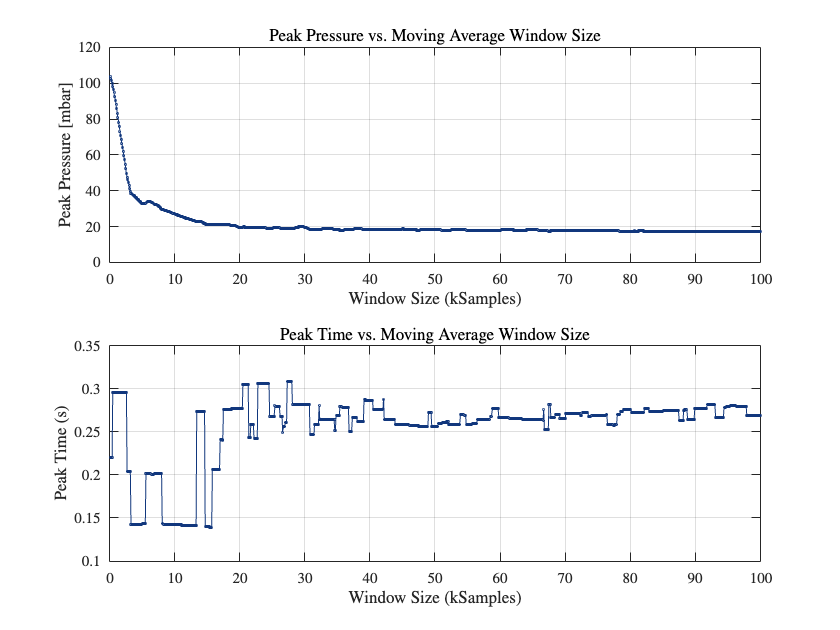

% Example: Vary window sizes from small to large
windowSizes = 100:100:100000;  % 1 MHz sampling => 100 to 100k
peakPressures = zeros(size(windowSizes));
peakTimes = zeros(size(windowSizes));

for i = 1:length(windowSizes)
    wSize = windowSizes(i);
    dataMovingAvg = movmean(dataLowPass, wSize);
    
    [peakVal, peakIdx] = max(dataMovingAvg);
    peakPressures(i) = peakVal;
    peakTimes(i) = t(peakIdx);
end

% Plot peak amplitude vs. window size
figure;
subplot(2,1,1);
plot(windowSizes/1000, peakPressures, '-o', MarkerSize=1.5,Color=LUBlue);
xlabel('Window Size (kSamples)');
ylabel('Peak Pressure [mbar]');
title('Peak Pressure vs. Moving Average Window Size');
grid on;

% Plot peak time vs. window size
subplot(2,1,2);
plot(windowSizes/1000, peakTimes, '-o', MarkerSize=1.5, Color=LUBlue);
xlabel('Window Size (kSamples)');
ylabel('Peak Time (s)');
title('Peak Time vs. Moving Average Window Size');
grid on;

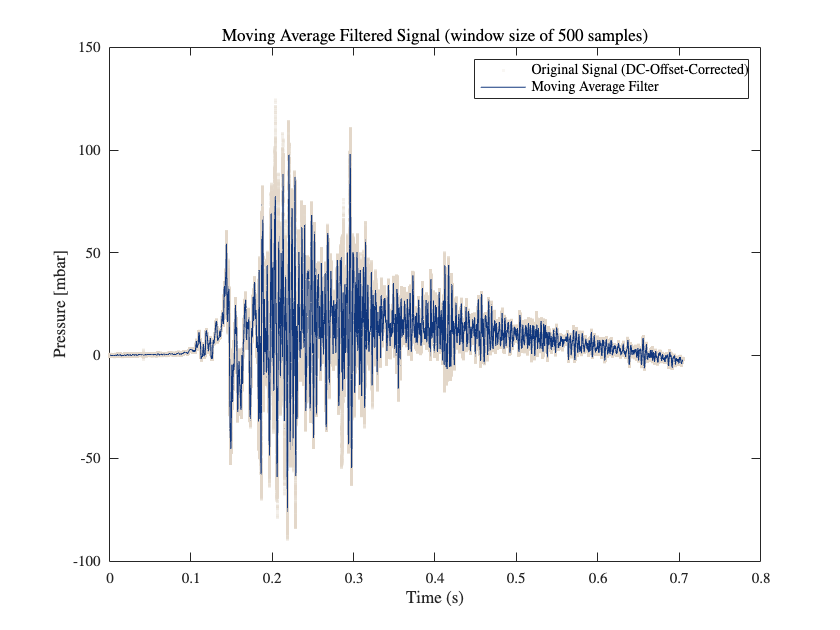

AvgFiltWind = 500;
dataMovingAvg = movmean(dataLowPass, AvgFiltWind);
figure;
scatter(t, data, '.', ...
    'MarkerEdgeColor', LUCopper_Light, ...
    'MarkerEdgeAlpha', 0.2);   % <--- Transparency set here (20% opaque)
hold on
plot(t, dataMovingAvg , 'LineWidth', .75, Color = LUBlue)
% title('Moving Average Filtered Signal');
title(sprintf("Moving Average Filtered Signal (window size of %.0f samples)", AvgFiltWind));
xlabel('Time (s)'); ylabel('Pressure [mbar]');
legend('Original Signal (DC-Offset-Corrected)',"Moving Average Filter")
box on
hold off

### 4.2 Weighted Moving Average

### **4.3 Median Filter**

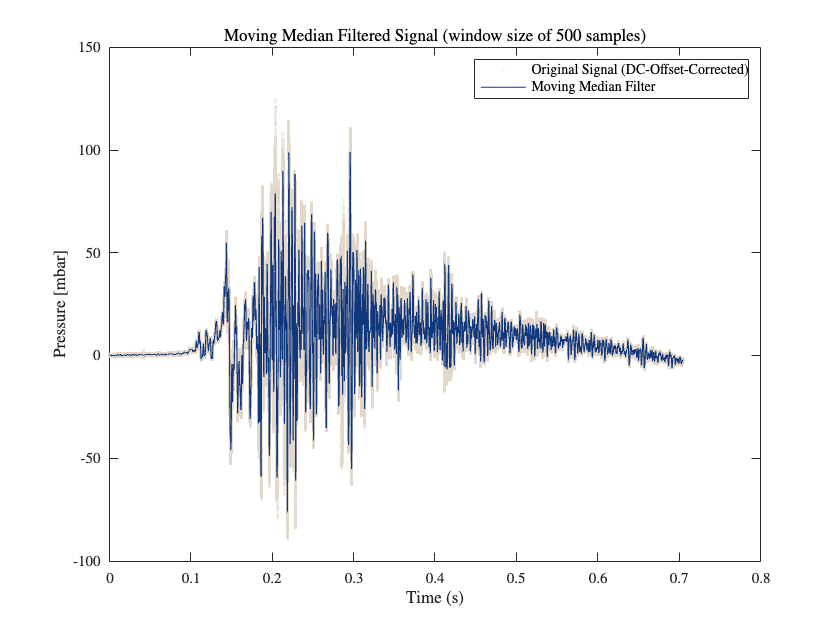

MedFiltWind = 500; 
dataMedFilt = medfilt1(dataLowPass,MedFiltWind,[],'truncate');
% dataMedFilt = medfilt1(data,MedFiltWind,'zeropad');
figure;
scatter(t, data, '.', ...
    'MarkerEdgeColor', LUCopper_Light, ...
    'MarkerEdgeAlpha', 0.2);   % <--- Transparency set here (20% opaque)
hold on
plot(t, dataMedFilt , 'LineWidth', .75, Color = LUBlue)
title(sprintf("Moving Median Filtered Signal (window size of %.0f samples)", MedFiltWind));
xlabel('Time (s)'); ylabel('Pressure [mbar]');
legend('Original Signal (DC-Offset-Corrected)',"Moving Median Filter")
box on
hold off

### 4.4 Design and Analyze Savitzky-Golay Filters

This example shows how to design, analyze, and apply Savitzky-Golay smoothing and differentiation filters to sampled signals with additive noise. The example also shows you how to use a weighting vector to optimize the frequency response and improve smoothness.

**Savitzky-Golay Filters**

Savitzly-Golay (SG) filters [[1]](https://se.mathworks.com/help/signal/ug/design-and-analysis-of-savitzky-golay-filters.html#mw_rtc_DesignAndAnalysisOfSavitzkyGolayFiltersExample_M_5c01) are digital FIR lowpass filters that operate by moving least-squares polynomial fitting to input data samples within an interval. You can use SG filters to smooth or differentiate signal data, aiming to reduce noise while preserving the overall shape of the signal. This code creates and smooths a noisy Gaussian peak signal by performing SG filtering.

**Filter Design**

SG filters are typically characterized by these parameters:

- *m*: Filter polynomial order, which is the degree of the lest-squares fitted polynomials used in the filter.

- ℓf: Frame length, which is the number of signal samples that form the interval width around the sample being filtered. Alternatively, the half-width interval *n*h can also characterize SG filters, where ℓf=2*n*h+1.

Design an SG filter using 6th-order polynomials and with the half width of 50 samples. Return the first differentiation filter.

% m = 3;
% nh = 100;
% 
% fl = 2*nh+1;
% 
% [~,gSG] = sgolay(m,fl);
% gSG = gSG(:,1);





Designing SG filters based on their cutoff frequency involves following guidelines that aim to provide a good approximation in the frequency response. Schmid et. al [[2]](https://se.mathworks.com/help/signal/ug/design-and-analysis-of-savitzky-golay-filters.html#mw_rtc_DesignAndAnalysisOfSavitzkyGolayFiltersExample_M_7035) propose a relation between the cutoff frequency *F*−3dB [[1]](https://se.mathworks.com/help/signal/ug/design-and-analysis-of-savitzky-golay-filters.html#mw_rtc_DesignAndAnalysisOfSavitzkyGolayFiltersExample_M_5c01) and the SG filter characteristic parameters (*m*,$n_h$). For a filter order *m*, filter half width *n*h, and a sample rate *F*s, the 3 dB cutoff frequency is


$$
F_{-3dB} = \frac{F_s}{6.352(n_
h
+1/2)/(m+1.379)-(0.513+0.316m)/(n_
h
+1/2)}


$$


This expression, obtained from least-squares fitting, is a good approximation for $n_h \geq 25$.

Compute the cutoff frequency for the SG filter using a sample rate of 1000 Hz.

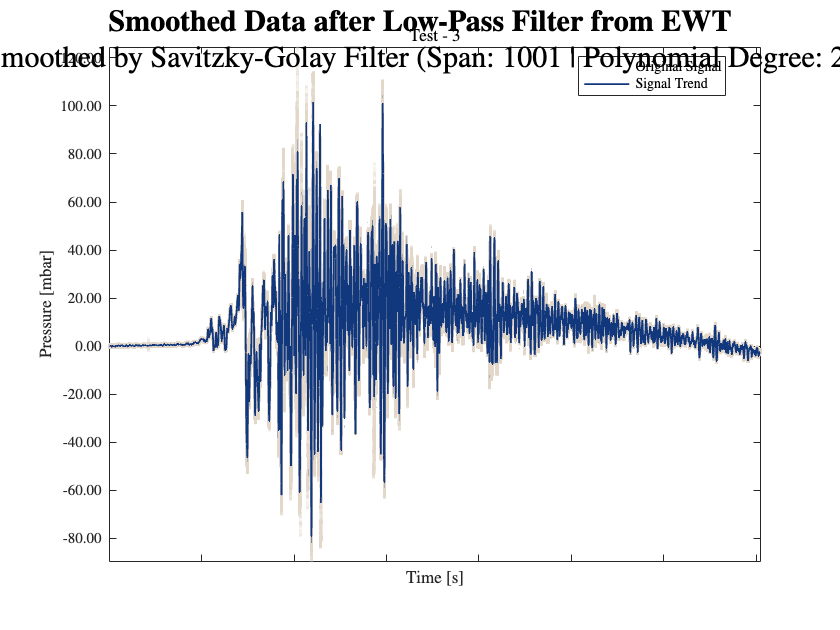

% % Smooth input data
% F3dB = Fs/(6.352*(nh+1/2)/(m+1.379) - ...
%          (0.513+0.316*m)/(nh+1/2));
% disp(F3dB/Fs)
% 
% [smoothedData,winSize] = smoothdata(data,"sgolay","SmoothingFactor",0.5, ...
%     "Degree",4,"SamplePoints",t);

% Display results
% figure
% plot(t,data,"SeriesIndex",6,"DisplayName","Input data")
% hold on
% plot(t,smoothedData,"SeriesIndex",1,"LineWidth",1.5, ...
%     "DisplayName","Smoothed data")
% hold off
% title("Moving window size: " + string(winSize));
% legend
% xlabel("t")
        span = 1001;
        polyOrder = 2;
        % Smooth the pressure signal
        dataSgolayFilt = smooth(dataLowPass, span, 'sgolay', polyOrder);     
                % Scatter plot of original signal
        scatter(t, data, '.', ...
            'MarkerEdgeColor', AuxFcn_GS.LUCopper_Light, ...
            'MarkerEdgeAlpha', 0.2);
        hold on;
        
        % Plot extracted trend (using your blue color)
        plot(t, dataSgolayFilt, 'Color', AuxFcn_GS.LUBlue, 'LineWidth', 1.2);
        ytickformat('%.2f')  % Uses compact engineering notation
        ax = gca;
        ax.YAxis.Exponent = 0;  % Disables scientific notation
        % Title and labels
        % title(['Extracted Signal Trend - Test - ' num2str(test_index)]);
        title(['Test - ' num2str(test_index)]);
        xlabel('Time [s]');
        ylabel('Pressure [mbar]');
        box on;
        legend('Original Signal', 'Signal Trend', 'Location', 'best');
        axis tight
        % s.XTickLabel={};
        set(gca,'xticklabel',[])
        sgtitle({'\textbf{Smoothed Data after Low-Pass Filter from EWT}',sprintf('Smoothed by Savitzky-Golay Filter (Span: %d | Polynomial Degree: %d)', span, polyOrder)},'fontsize',20)

## 5. Selecting the Optimal Window

In practice, you visually or programmatically identify where both curves plateau. For instance, if peakPressures changes < 1% after 2000 samples, and peakTimes stabilizes around the same window size, you pick that.

## 6. Final Peak Detection

Suppose we choose a window size = 2000 from the analysis

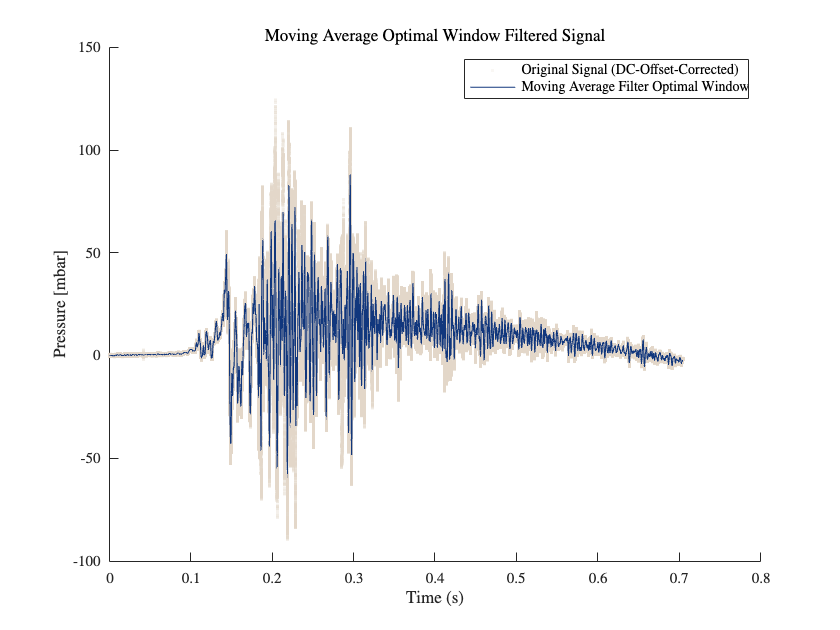

optimalWindow = 1000;
dataMovingAvgOpt = movmean(dataLowPass, optimalWindow);
[peakValOpt, peakIdxOpt] = max(dataMovingAvgOpt);
peakTimeOpt = t(peakIdxOpt);

figure;
% scatter(t, data,'.',Color = [197/255, 204/255, 221/255])
scatter(t, data, '.', ...
    'MarkerEdgeColor', LUCopper_Light, ...
    'MarkerEdgeAlpha', 0.2);   % <--- Transparency set here (20% opaque)
hold on
plot(t, dataMovingAvgOpt , 'LineWidth', .75, Color = LUBlue)
title('Moving Average Optimal Window Filtered Signal');
xlabel('Time (s)'); ylabel('Pressure [mbar]');
legend('Original Signal (DC-Offset-Corrected)',"Moving Average Filter Optimal Window")
hold off

disp('------------------ Final Peak Detection ------------------');

------------------ Final Peak Detection ------------------


fprintf('Chosen window size: %d samples\n', optimalWindow);

Chosen window size: 1000 samples


fprintf('Peak Pressure: %.3f [mbar]\n', peakValOpt);

Peak Pressure: 88.032 [mbar]


fprintf('Peak Time: %.6f s\n', peakTimeOpt);

Peak Time: 0.295781 s


## 7. Methods Comparison

### 7.1 Simple Smoothing Techniques (Baseline for Comparison)

**Moving Average Filter**

windowSize = 20000;  % Example window
dataSmoothed = movmean(data, windowSize);
[peakSmoothAmp, idxSmooth] = max(dataSmoothed);
peakSmoothTime = t(idxSmooth);

### 7.2 Advanced Frequency-Based Filtering

**Low-pass filter**

dataFiltered = dataLowPass;
% dataFiltered = dataBandPass;
[peakFiltAmp, idxFilt] = max(dataFiltered);
peakFiltTime = t(idxFilt);

**Analyze Savitzky-Golay Filter**

### 7.3 Filter + Smoothing

(Apply smoothing to your already-filtered data.)

dataFiltSmooth = movmean(dataFiltered, windowSize);
[peakFiltSmoothAmp, idxFiltSmooth] = max(dataFiltSmooth);
peakFiltSmoothTime = t(idxFiltSmooth);

### Reference: Raw Data

[peakRawAmp, idxRaw] = max(data);
peakRawTime = t(idxRaw);

### Compute Peak Differences

peakAmpDiff_Filt        = ((peakFiltAmp - peakRawAmp)/peakRawAmp)*100;
peakAmpDiff_Smooth      = ((peakSmoothAmp - peakRawAmp)/peakRawAmp)*100;
peakAmpDiff_FiltSmooth  = ((peakFiltSmoothAmp - peakRawAmp)/peakRawAmp)*100;

timeShift_Filt          = peakFiltTime - peakRawTime;
timeShift_Smooth        = peakSmoothTime - peakRawTime;
timeShift_FiltSmooth    = peakFiltSmoothTime - peakRawTime;

### Compute Residual Noise (RMS)

% As a simple example, define a region outside the main peak (e.g., everything
% except ±X samples from the peak) to estimate noise. Adjust as needed for your data.

peakRegion = 1000;  % number of samples around the peak to exclude

excludeStart = max(idxRaw - peakRegion, 1);
excludeEnd   = min(idxRaw + peakRegion, length(data));

noiseRegion = setdiff(1:length(data), excludeStart:excludeEnd);

noiseRaw       = rms(data(noiseRegion));
noiseFilt      = rms(dataFiltered(noiseRegion));
noiseSmooth    = rms(dataSmoothed(noiseRegion));
noiseFiltSmooth= rms(dataFiltSmooth(noiseRegion));

### Display Results

methodsCompare = {'Raw', 'Only Filter', 'Only Smooth', 'Filter+Smooth'};
peakAmp = [peakRawAmp, peakFiltAmp, peakSmoothAmp, peakFiltSmoothAmp];
timePeak = [peakRawTime, peakFiltTime, peakSmoothTime, peakFiltSmoothTime];
peakAmpDiff = [0, peakAmpDiff_Filt, peakAmpDiff_Smooth, peakAmpDiff_FiltSmooth];
timeShift   = [0, timeShift_Filt, timeShift_Smooth, timeShift_FiltSmooth];
noiseRMS    = [noiseRaw, noiseFilt, noiseSmooth, noiseFiltSmooth];
comparisonTable = table(methodsCompare', peakAmp', timePeak', ...
    peakAmpDiff', timeShift', noiseRMS', ...
    'VariableNames', {...
    'Method', ...
    'PeakAmp', ...
    'PeakTime_s', ...
    'RelPeakAmpDiff_vsRaw', ...
    'TimeShift_vsRaw_s', ...
    'NoiseRMS'});
disp(comparisonTable);

         Method          PeakAmp    PeakTime_s    RelPeakAmpDiff_vsRaw    TimeShift_vsRaw_s    NoiseRMS
    _________________    _______    __________    ____________________    _________________    ________

    {'Raw'          }    124.44      0.20379                  0                      0           18.47 
    {'Only Filter'  }    103.98      0.22045            -16.439               0.016655           18.01 
    {'Only Smooth'  }    19.864      0.27731            -84.037               0.073521          10.592 
    {'Filter+Smooth'}    19.718       0.2773            -84.154               0.073511          10.592 



### Plot

% figure('Name','Comparison of Filter vs. Smoothing','NumberTitle','off');
% subplot(2,2,1);
% bar(categorical(methodsCompare), peakAmp);
% title('Peak Amplitude'); ylabel('Amplitude'); grid on;
% 
% subplot(2,2,2);
% bar(categorical(methodsCompare), timePeak);
% title('Peak Time'); ylabel('Time (s)'); grid on;
% 
% subplot(2,2,3);
% bar(categorical(methodsCompare), peakAmpDiff);
% title('Peak Amp Difference vs. Raw'); ylabel('Amplitude'); grid on;
% subplot(2,2,4);
% bar(categorical(methodsCompare), noiseRMS);
% title('RMS Noise'); ylabel('Amplitude (RMS)'); grid on;

% figure('Name','Comparison of Filter vs. Smoothing','NumberTitle','off');
% subplot(2,2,1);
% hBar1 = bar(categorical(methodsCompare, methodsCompare, 'Ordinal', true), peakAmp, 'FaceColor','flat'); 
% title('Peak Amplitude'); ylabel('Amplitude'); grid on;
% 
% % Assign different colors for each bar
% cMap = lines(numel(methodsCompare));   % Grab distinct colors
% for i = 1:numel(methodsCompare)
%     hBar1.CData(i,:) = cMap(i,:);
% end
% 
% subplot(2,2,2);
% hBar2 = bar(categorical(methodsCompare, methodsCompare, 'Ordinal', true), timePeak, 'FaceColor','flat');
% title('Peak Time'); ylabel('Time (s)'); grid on;
% for i = 1:numel(methodsCompare)
%     hBar2.CData(i,:) = cMap(i,:);
% end
% 
% subplot(2,2,3);
% hBar3 = bar(categorical(methodsCompare, methodsCompare, 'Ordinal', true), peakAmpDiff, 'FaceColor','flat');
% title('Peak Amp Difference vs. Raw'); ylabel('Amplitude'); grid on;
% for i = 1:numel(methodsCompare)
%     hBar3.CData(i,:) = cMap(i,:);
% end
% 
% subplot(2,2,4);
% hBar4 = bar(categorical(methodsCompare, methodsCompare, 'Ordinal', true), noiseRMS, 'FaceColor','flat');
% title('RMS Noise'); ylabel('Amplitude (RMS)'); grid on;
% for i = 1:numel(methodsCompare)
%     hBar4.CData(i,:) = cMap(i,:);
% end

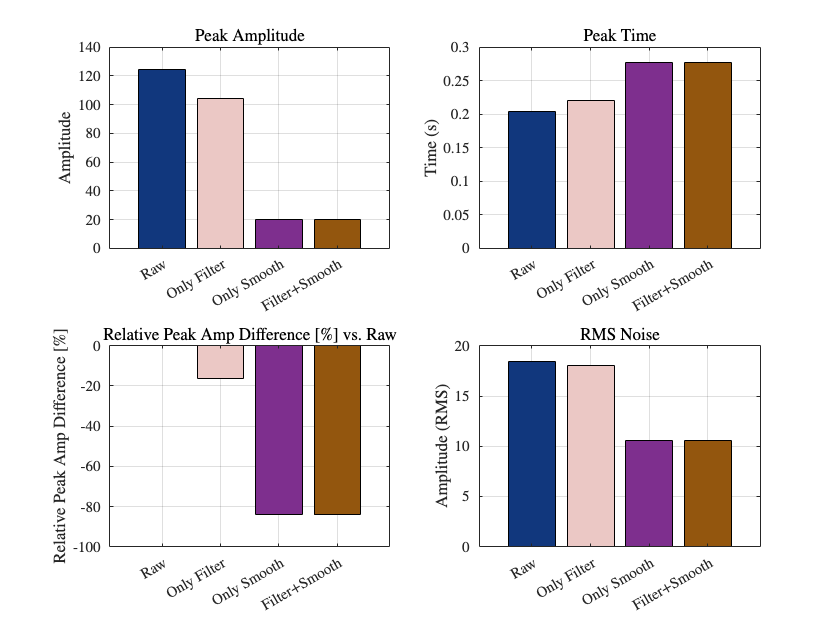

%% Define methods and custom colors

% methodsCompare = {'Raw', 'Only Filter', 'Only Smooth', 'Filter+Smooth'};
% 
% peakAmp = [peakRawAmp, peakFiltAmp, peakSmoothAmp, peakFiltSmoothAmp];
% timePeak = [peakRawTime, peakFiltTime, peakSmoothTime, peakFiltSmoothTime];
% peakAmpDiff = [0, peakAmpDiff_Filt, peakAmpDiff_Smooth, peakAmpDiff_FiltSmooth];
% timeShift   = [0, timeShift_Filt, timeShift_Smooth, timeShift_FiltSmooth];
% noiseRMS    = [noiseRaw, noiseFilt, noiseSmooth, noiseFiltSmooth];

colorMapMethods = containers.Map();
colorMapMethods('Raw')           = LUBlue;% LU-blue  (LU-Brand)
colorMapMethods('Only Filter')   = Red_Light; %pink / light red
colorMapMethods('Only Smooth')   = [0.4940, 0.1840, 0.5560]; % purple
colorMapMethods('Filter+Smooth') = LUCopper; % LU-Copper (LU-Brand)

figure('Name','Comparison of Filter vs. Smoothing','NumberTitle','off');

%--- Subplot (1) Peak Amplitude ---%
subplot(2,2,1);
hBar1 = bar(categorical(methodsCompare, methodsCompare, 'Ordinal', true), peakAmp, 'FaceColor','flat'); 
title('Peak Amplitude'); ylabel('Amplitude'); grid on;

% Assign custom colors
for i = 1:numel(methodsCompare)
    methodName = methodsCompare{i};
    hBar1.CData(i,:) = colorMapMethods(methodName);
end

%--- Subplot (2) Peak Time ---%
subplot(2,2,2);
hBar2 = bar(categorical(methodsCompare, methodsCompare, 'Ordinal', true), timePeak, 'FaceColor','flat');
title('Peak Time'); ylabel('Time (s)'); grid on;
for i = 1:numel(methodsCompare)
    methodName = methodsCompare{i};
    hBar2.CData(i,:) = colorMapMethods(methodName);
end

%--- Subplot (3) Peak Amp Difference vs. Raw ---%
subplot(2,2,3);
hBar3 = bar(categorical(methodsCompare, methodsCompare, 'Ordinal', true), peakAmpDiff, 'FaceColor','flat');
title('Relative Peak Amp Difference [\%] vs. Raw'); ylabel('Relative Peak Amp Difference [\%]','Interpreter','latex'); grid on;
for i = 1:numel(methodsCompare)
    methodName = methodsCompare{i};
    hBar3.CData(i,:) = colorMapMethods(methodName);
end

%--- Subplot (4) RMS Noise ---%
subplot(2,2,4);
hBar4 = bar(categorical(methodsCompare, methodsCompare, 'Ordinal', true), noiseRMS, 'FaceColor','flat');
title('RMS Noise'); ylabel('Amplitude (RMS)'); 
grid on;
for i = 1:numel(methodsCompare)
    methodName = methodsCompare{i};
    hBar4.CData(i,:) = colorMapMethods(methodName);
end

## 8. Optional: Further Refinements

- Automate plateau detection

- Savitzky-Golay smoothing

- Wavelet denoising

- Segment the data if extremely large